load sampleEEGdata.mat

e1 = [2,7,8];
data = EEG.data(e1,:,:);

ndiv = 24;
freq2anl = linspace(2,30,ndiv);

fftcoeff = zeros(length(e1), length(freq2anl), EEG.pnts, EEG.trials);

time = -1:1/EEG.srate:1;
hf_wv_size = (length(time) - 1)/2;
n_signal = EEG.pnts;
n_wavelet = length(time);

n_conv = n_signal + n_wavelet - 1;
n_conv_pow2 = pow2(nextpow2(n_conv));

fft_signal = fft(data, n_conv_pow2, 2);

for fi = 1:length(freq2anl)
    s = 6/(2*pi*freq2anl(fi));
    m_wlet = exp(2*pi*freq2anl(fi)*1i.*time).*exp((-time.^2)./(2*s^2));
    fft_w = fft(m_wlet, n_conv_pow2);
    
    conv_signal = fft_signal.*fft_w;
    ifft_s = ifft(fft_signal.*fft_w, n_conv_pow2,2);
    ifft_s = ifft_s(:,1:n_conv,:);
    fftcoeff(:,fi,:,:) = ifft_s(:,hf_wv_size + 1:end-hf_wv_size,:);
end

ans =      3    24   640    99


e = 2

e = 2

tf_mean_pow = mean(abs(fftcoeff).^2, 4);
db_corrected = zeros(length(e1), length(freq2anl), EEG.pnts);

baselinetime = [-400 -100]; % in ms
[~, baselineidx(1)] = min(abs(EEG.times-baselinetime(1)));
[~, baselineidx(2)] = min(abs(EEG.times-baselinetime(2)));
baseline_power = mean(tf_mean_pow(:,:,baselineidx(1):baselineidx(2)),3);

db_corrected = 10*log10(bsxfun(@rdivide, tf_mean_pow, baseline_power));

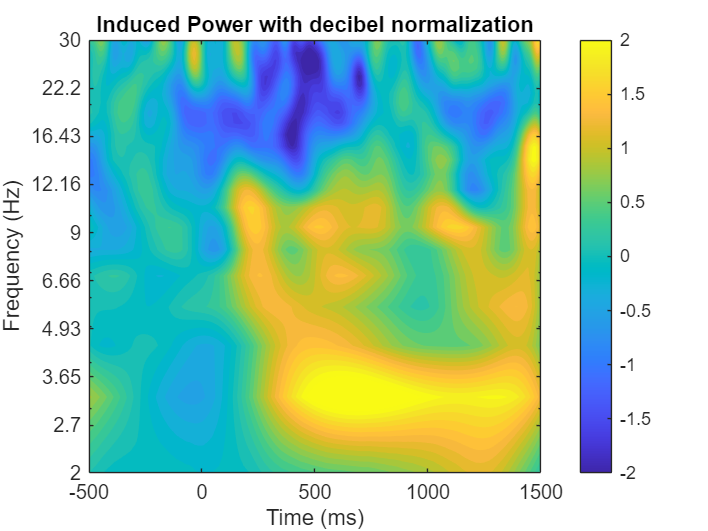

figure;
contourf(EEG.times, freq2anl, squeeze(db_corrected(e,:,:)),40,'linecolor','none')
set(gca,'ytick',round(logspace(log10(freq2anl(1)),log10(freq2anl(end)),10)*100)/100,'yscale','log','xlim',[-500 1500],'clim',[-2 2])
title("Induced Power with decibel normalization")
xlabel("Time (ms)")
ylabel("Frequency (Hz)")
colorbar;

tf_pow_mean = abs(mean(fftcoeff,4)).^2;
db_corrected_2 = zeros(length(e1), length(freq2anl), EEG.pnts);

baselinetime = [-400 -100]; % in ms
[~, baselineidx(1)] = min(abs(EEG.times-baselinetime(1)));
[~, baselineidx(2)] = min(abs(EEG.times-baselinetime(2)));
baseline_power = mean(tf_pow_mean(:,:,baselineidx(1):baselineidx(2)),3);

db_corrected_2 = 10*log10(bsxfun(@rdivide, tf_pow_mean, baseline_power));

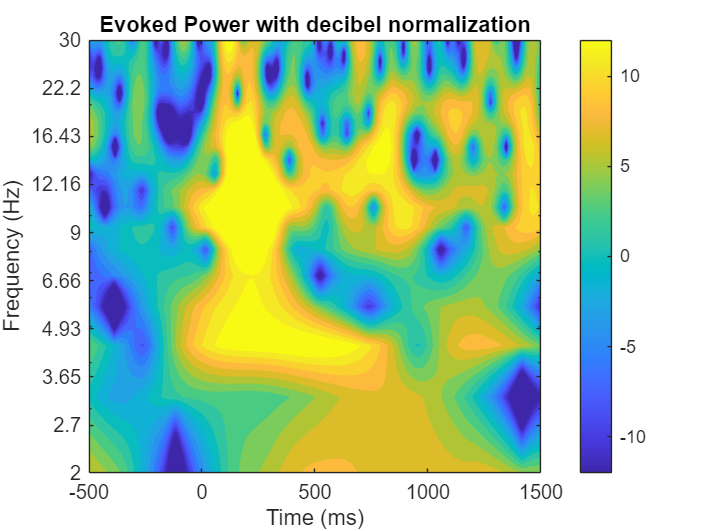

figure;
contourf(EEG.times, freq2anl, squeeze(db_corrected_2(e,:,:)),40,'linecolor','none');
set(gca,'ytick',round(logspace(log10(freq2anl(1)),log10(freq2anl(end)),10)*100)/100,'yscale','log','xlim',[-500 1500],'clim',[-12 12]);
title("Evoked Power with decibel normalization");
xlabel("Time (ms)");
ylabel("Frequency (Hz)");
colorbar;

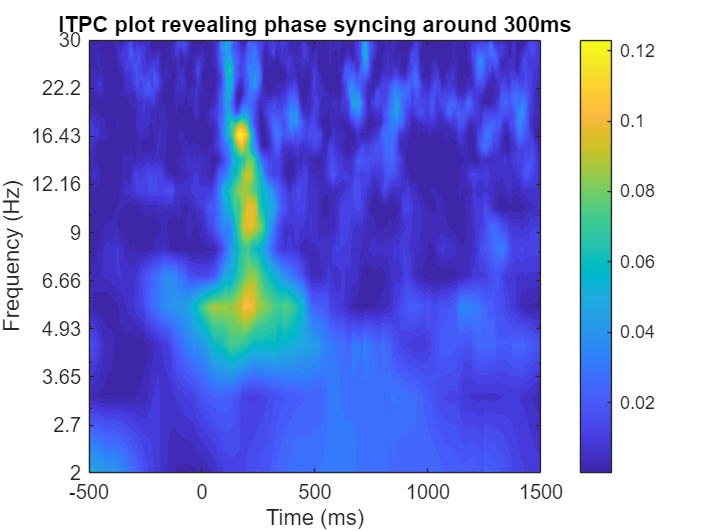

itpc = abs(mean(exp(1i*angle(fftcoeff)),4)).^2;
contourf(EEG.times, freq2anl, squeeze(itpc(e,:,:)),40,'linecolor','none');
set(gca,'ytick',round(logspace(log10(freq2anl(1)),log10(freq2anl(end)),10)*100)/100,'yscale','log', 'xlim',[-500 1500]);
title("ITPC plot revealing phase syncing around 300ms");
xlabel("Time (ms)");
ylabel("Frequency (Hz)");
colorbar;

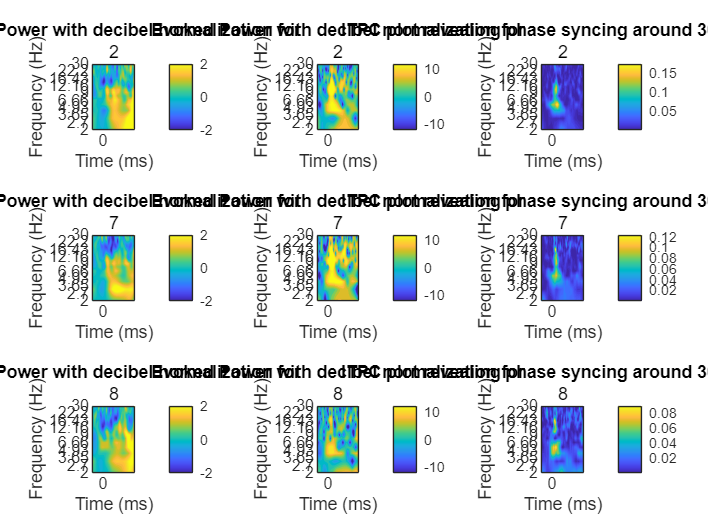

figure;
tiledlayout(3,3)
for ei = 1:length(e1)
    nexttile();
    contourf(EEG.times, freq2anl, squeeze(db_corrected(ei,:,:)),40,'linecolor','none')
    set(gca,'ytick',round(logspace(log10(freq2anl(1)),log10(freq2anl(end)),10)*100)/100,'yscale','log','xlim',[-500 1500],'clim',[-2 2])
    title("Induced Power with decibel normalization for ", e1(ei))
    xlabel("Time (ms)")
    ylabel("Frequency (Hz)")
    colorbar;

    nexttile();
    contourf(EEG.times, freq2anl, squeeze(db_corrected_2(ei,:,:)),40,'linecolor','none');
    set(gca,'ytick',round(logspace(log10(freq2anl(1)),log10(freq2anl(end)),10)*100)/100,'yscale','log','xlim',[-500 1500],'clim',[-12 12]);
    title("Evoked Power with decibel normalization for", e1(ei));
    xlabel("Time (ms)");
    ylabel("Frequency (Hz)");
    colorbar;

    nexttile();
    contourf(EEG.times, freq2anl, squeeze(itpc(ei,:,:)),40,'linecolor','none');
    set(gca,'ytick',round(logspace(log10(freq2anl(1)),log10(freq2anl(end)),10)*100)/100,'yscale','log', 'xlim',[-500 1500]);
    title("ITPC plot revealing phase syncing around 300ms for ", e1(ei));
    xlabel("Time (ms)");
    ylabel("Frequency (Hz)");
    colorbar;
end